# **Predicción de la velocidad del aire real (TAS) a partir de otros sensores**

Este ejemplo muestra cómo usar información historica para entrenar un modelo de regresión que prediga la TAS a partir de las mediciones de otros sensores. Modelos como este son usados en aplicaciones de control donde es deseable usar un estimador no lineal para una variable que no es observable directamente o que es muy costosa de medir. Además, las simulaciones y los estudios preliminares de factibilidad usan modelos como este donde un modelo basado en principios físicos es muy complejo de crear o toma mucho tiempo para ser simulado.

## Importación de los datos desde Excel

Lo primero es traer los datos a MATLAB. La función [importFlightData](matlab:open('./importFlightData.m')) fue creada automáticamente usando el [Import Tool](https://www.mathworks.com/help/matlab/ref/importtool.html), de tal forma que se generó código que refleja nuestras acciones interactivas. Esto nos permite personalizar la importación sin pensar en programarlo todo nosotros mismos.

pth = strcat(pwd,'\','FlightData.xlsx');
FlightData = importFlightData(pth);

## Exploración de los datos

Las tablas no son objetos estáticos. Podemos interactuar con las columnas para explorar rangos y filtrar información. MATLAB va a sugerirnos el código para que la próxima vez no tengamos que repetir la misma acción. Por ejemplo, cuando graficamos los datos de los sensores tal como vienen, vemos que el vuelo termina en el Ecuador. Pero cuando vemos los valores de la TAS, resulta que hay muchos valores en cero que no tienen sentido. Podemos removerlos interactivamente en la tabla, y también podemos usar [Live Controls](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html) para experimentar con diferentes valores y así explorar varias alternativas rápidamente.

FlightData

FlightData = 47312×14 table
            Time            FuelQuantity    OilPressure    OilTemperature    LatitudePosition    LongitudePosition    Altitude    ExhaustTemperature    FuelFlow    FanSpeed    TrueAirSpeed    WindDirection    WindSpeed    WeightOnWheels
    ____________________    ____________    ___________    ______________    ________________    _________________    ________    __________________    ________    ________    ____________    _____________    _________    ______________

    02-Jun-2001 05:41

% FlightData = FlightData(FlightData.TrueAirSpeed >= 80, :)

## Visualización

Podemos comunicar más información mezclando colores en una gráfica normal, además de que no tenemos que saber el código para poner ejes, leyendas, etc.

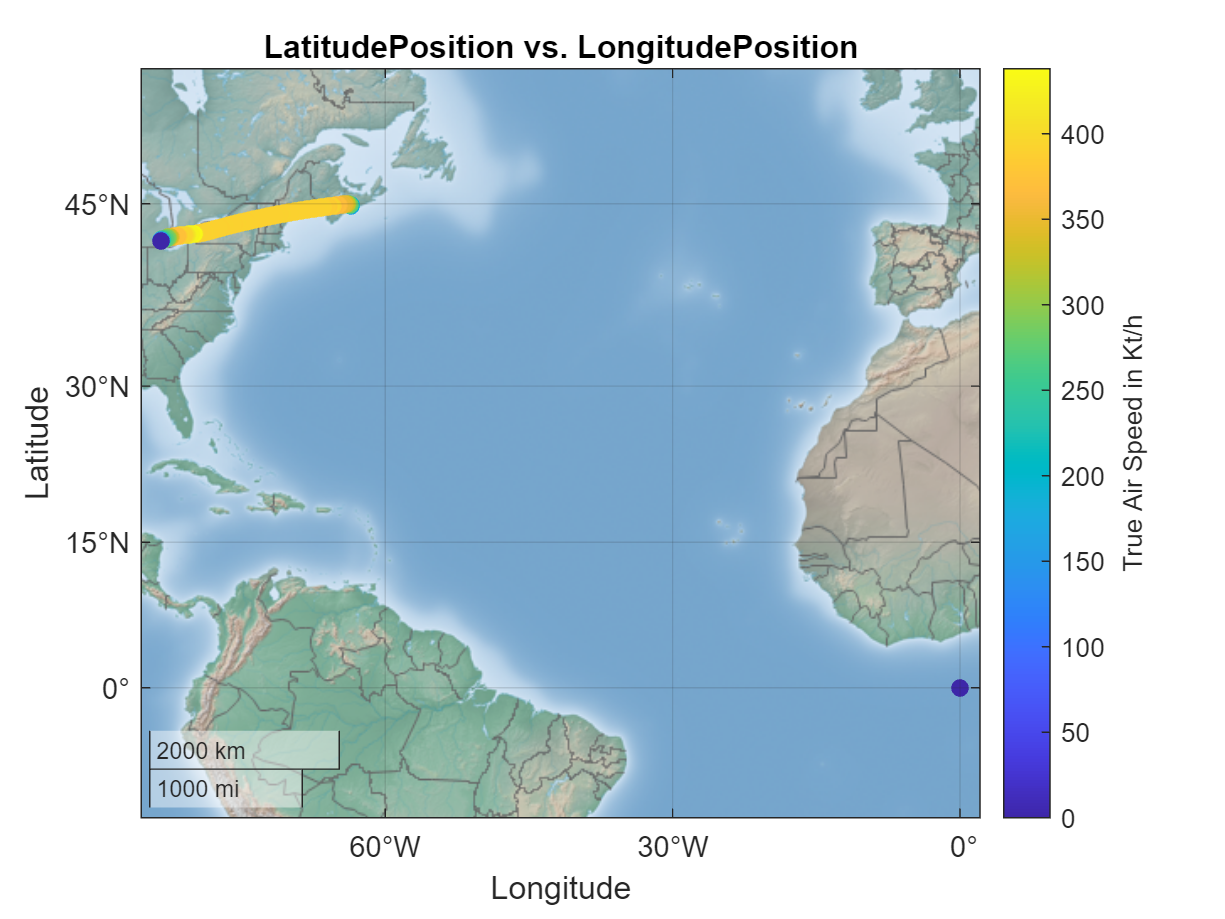

% Create geoplot of FlightData.LatitudePosition and FlightData.LongitudePosition
lat = FlightData.LatitudePosition(1:10:end);
lon = FlightData.LongitudePosition(1:10:end);
TAS = FlightData.TrueAirSpeed(1:10:end);

h = geoscatter(lat,lon,36,TAS,"filled");
C = colorbar("eastoutside");
C.Label.String = "True Air Speed in Kt/h";

% Add title
title("LatitudePosition vs. LongitudePosition")
geobasemap colorterrain

Para crear gráficas, no es necesario salirnos del Live Script. A través de las tareas interactivas, podemos traer algunas de las funciónes de las apps y crear gráficas sin escribir código.

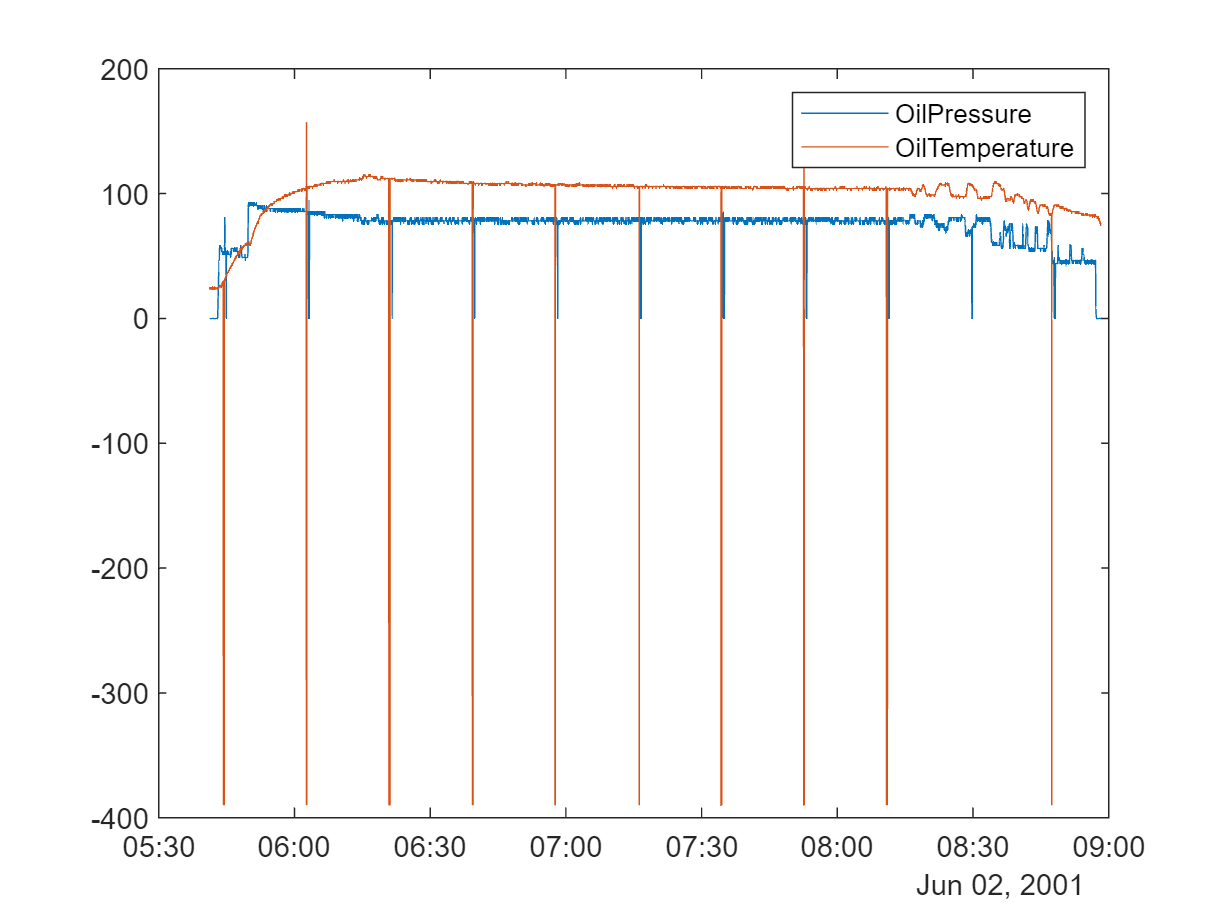

figure
% Create plot of FlightData.Time and FlightData.OilPressure
plot(FlightData.Time,FlightData.OilPressure,"DisplayName","OilPressure");

hold on
% Create plot of FlightData.Time and FlightData.OilTemperature
plot(FlightData.Time,FlightData.OilTemperature,"DisplayName","OilTemperature");
hold off

legend

## Preprocesamiento: interpolar datos anómalos

A través de la app [Data Cleaner](https://www.mathworks.com/help/matlab/ref/datacleaner-app.html) podemos limpiar nuestros datos removiendo tendencias, interpolando datos faltantes, o removiendo datos anomalos, entre otros. La función que aparece a continuación ([cleanOilSensors](matlab:open('./cleanOilSensors.m'))) fue generada automáticamente.

FlightDataClean = cleanOilSensors(FlightData);

## Modelado a través de una regresión

Podemos modelar la TAS a través de un modelo de regresión. Esto implica que a partir de variables medibles y accesibles vamos a usar una función para encontrar la TAS. La app de [Regression Learner](https://www.mathworks.com/help/stats/regression-learner-app.html) nos permite entrenar rápidamente modelos ya pre-entrenados. Vamos a usar un bagged decision tree con las opciones por defecto, el cual nos produce resultados considerablemente buenos. Por brevedad, no vamos a separar los datos para una validación.

mdl = trainTASModel(FlightDataClean)

mdl = struct with fields:
            predictFcn: @(x)ensemblePredictFcn(predictorExtractionFcn(x))
     RequiredVariables: {'Altitude'  'ExhaustTemperature'  'FanSpeed'  'FuelFlow'  'FuelQuantity'  'OilPressure'  'OilTemperature'  'WindDirection'  'WindSpeed'}
    RegressionEnsemble: [1×1 classreg.learning.regr.RegressionBaggedEnsemble]
                 About: 'This struct is a trained model exported from Regression Learner R2022a.'
          HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see <a href="matlab:helpview(fullfile(docroot, 'stats', 'stats.map'), 'appregression_exportmodeltoworkspace')">How to predict using an exported model</a

PredictedAirSpeed = mdl.predictFcn(FlightDataClean);


figure
% Create plot of FlightDataClean.Time and FlightDataClean.TrueAirSpeed
plot(FlightDataClean.Time,FlightDataClean.TrueAirSpeed,"DisplayName","TrueAirSpeed");

hold on
% Create plot of FlightDataClean.Time and PredictedAirSpeed
plot(FlightDataClean.Time,PredictedAirSpeed,"DisplayName","PredictedAirSpeed");
hold off

legend

## Importancia de los predictores

¿Cuáles medidas son más importantes para la predicción? Al crear la regresión, MATLAB nos brinda una medida de la importancia de los predictores. Esto nos sirve para comparar si el modelo termina dandole peso a las variables que nosotros esperabamos fueran importantes.

figure
bar(mdl.RegressionEnsemble.predictorImportance)
xticklabels(mdl.RequiredVariables)